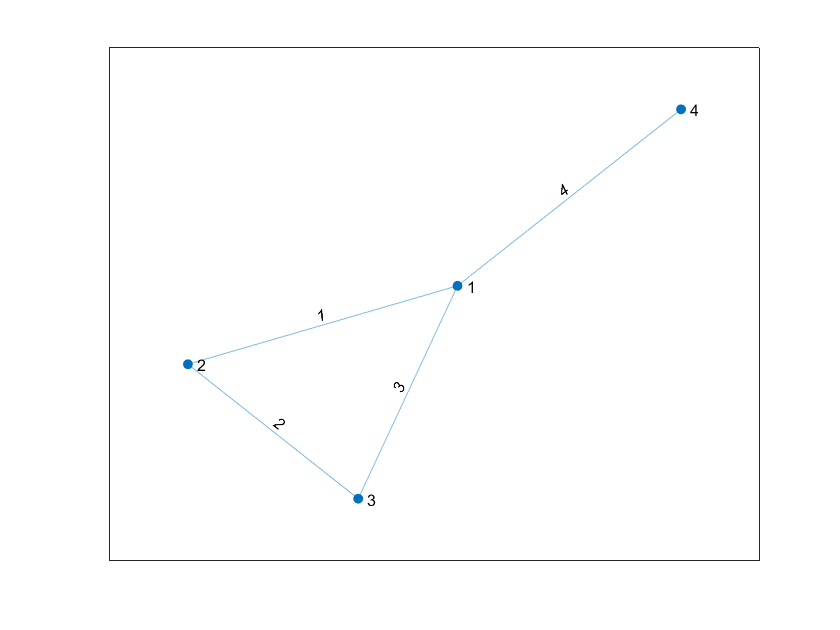

s1=[1,2,3,4];
t1=[2,3,1,1];
w1=[1,2,3,4];
G1 = graph(s1,t1,w1);
% set(gca,'XTick',[],'YTick',[])  %不显示坐标轴
plot(G1,'EdgeLabel',G1.Edges.Weight)

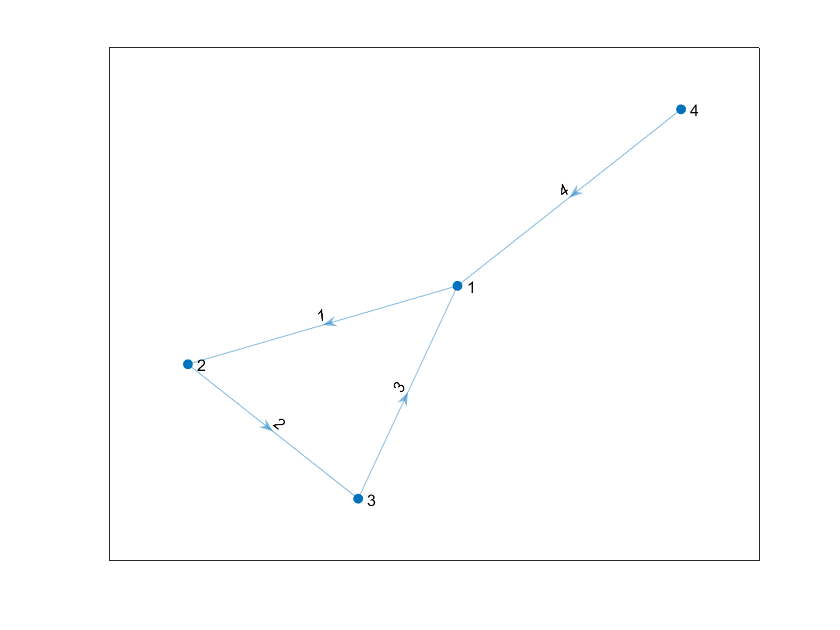

s1=[1,2,3,4];
t1=[2,3,1,1];
w1=[1,2,3,4];
G2 = digraph(s1,t1,w1);
% set(gca,'XTick',[],'YTick',[])  %不显示坐标轴
plot(G2,'EdgeLabel',G2.Edges.Weight)

% [p,d]=shortestpath(G1,2,4,positive) 迪杰斯特拉

p =      2     1     4


d = 5

% [p,d]=shortestpath(G1,2,4,mixed) 福特 仅适用于有向图

s3=[1,1,1,2,2,2,3,3,4,5,6,6,7,7];
t3=[9,7,2,8,5,3,4,5,5,6,7,8,8,9];
w3=[4,3,8,2,4,7,9,14,10,2,6,6,1,8];
G3=graph(s3,t3,w3);
D3=distances(G3);
disp(D3);

     0     6    13    20    10     9     3     4     4
     6     0     7    14     4     6     3     2    10
    13     7     0     9    11    13    10     9    17
    20    14     9     0    10    12    17    16    24
    10     4    11    10     0     2     7     6    14
     9     6    13    12     2     0     6     6    13
     3     3    10    17     7     6     0     1     7
     4     2     9    16     6     6     1     0     8
     4    10    17    24    14    13     7     8     0



[p,d]=shortestpath(G3,9,4)

p =      9     1     7     8     2     5     4


d = 24

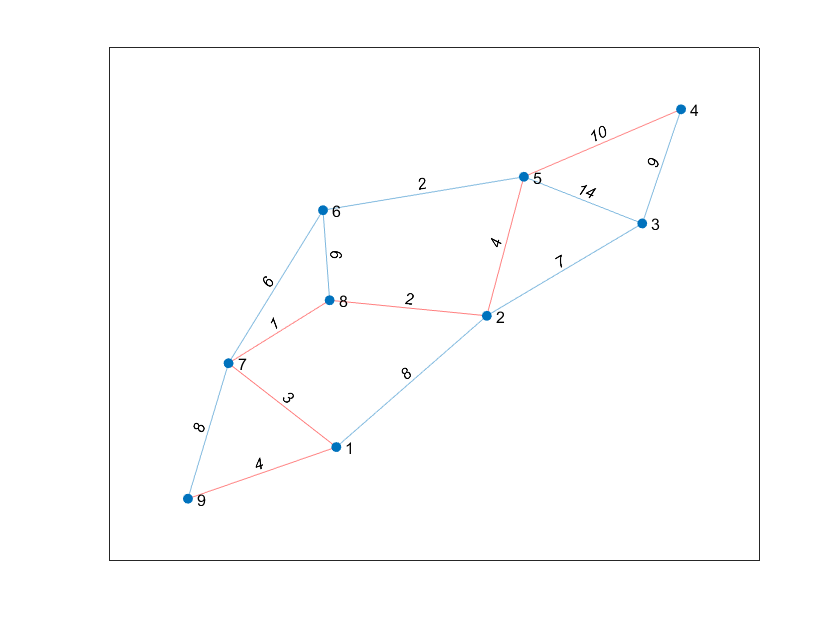

myplot=plot(G3,'EdgeLabel',G3.Edges.Weight);
highlight(myplot,p,'EdgeColor','red');

[nodeIDs,dist]=nearest(G3,2,10);
disp(nodeIDs);

     8
     7
     5
     1
     6
     3
     9



disp(dist);

     2
     3
     4
     6
     6
     7
    10

